dial_error=6

dial_error = 6

voltage_error=.01

voltage_error = 0.0100


data_calibration=csvread('calibration.csv',1);

x=data_calibration(:,1);
yerr=dial_error*ones(23,1);
y=data_calibration(:,2);

X=[ones(23,1) x];
[a,aerr,b,berr]=my_fit(x, y, yerr);
B=[ a b ]';
calibration = [a aerr; b berr]

calibration =    1.0e+03 *

    2.4562    0.0090
   -0.0036    0.0000


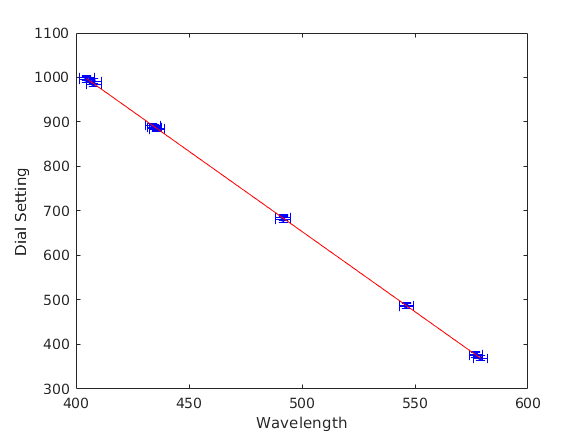


xerr=sqrt(yerr.^2/b^2+aerr^2/b^2+berr^2*y.^2/b^4);

p=plot(x, y, 'b.');
p.MarkerSize=10;
hold on;
line=errorbar(x,y, yerr);
line.LineStyle='none';
line.Color='b';
line=errorbar(x,y, xerr, 'horizontal');
line.Color='b';
line.LineStyle='none';
%errorbar(x, y, yerr, 'b', 'horizontal')
fit=linspace(min(x),max(x),10)';
plot(fit, [ones(size(fit)) fit]*B, '-r');
ylabel('Dial Setting');
xlabel('Wavelength');
hold off;

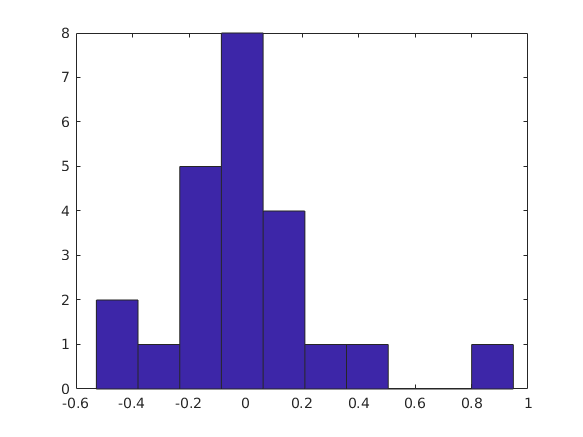

Chi=(y-(a+b.*x))./yerr;
hist(Chi)

%hold on
% plot(x, Chi2)
Chi2=sum(Chi.^2)

Chi2 = 1.9746

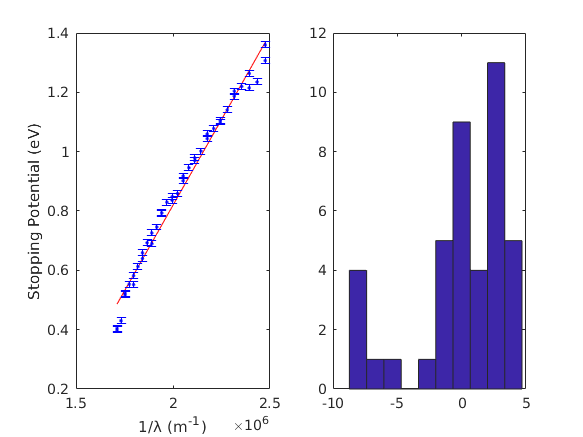

 % Curve 1, .5 mm
data_1=csvread('curve_1.csv',1);
x1=data_1(:,1);
y1=data_1(:,2);
d=size(x1);
x1err=dial_error*ones(d);
y1err=voltage_error*ones(d);
[x1,x1err]=convert(x1,x1err,calibration);

[a,aerr,b,berr]=my_fit(x1, y1, y1err);
B1=[a; b];
%l=errorbar(x,y, yerr);
%l.LineStyle='none';
%l.Color='b';
%l=errorbar(x,y, xerr, 'horizontal');
%l.LineStyle='none';
%l.Color='b';


data_2=csvread('curve_2.csv',1);
x2=data_2(:,1);
y2=data_2(:,2);
d=size(x2);
x2err=dial_error*ones(d);
y2err=voltage_error*ones(d);
[x2,x2err]=convert(x2,x2err,calibration);

[a,aerr,b,berr]=my_fit(x2, y2, y2err);
B2=[ a b ]';

line=linspace(min(x1),max(x1),10)';
subplot(1,2,1)
plot(x1, y1, '.');
hold on
plot(line, [ones(size(line)) line]*B1, '-r');
xlabel('1/λ (m^{-1})')
ylabel('Stopping Potential (eV)')
errorbar(x1, y1, y1err, 'b.')
hold off

subplot(1,2,2)
Chi=(y1-[ones(size(x1)) x1]*B1)./y1err;
hist(Chi)

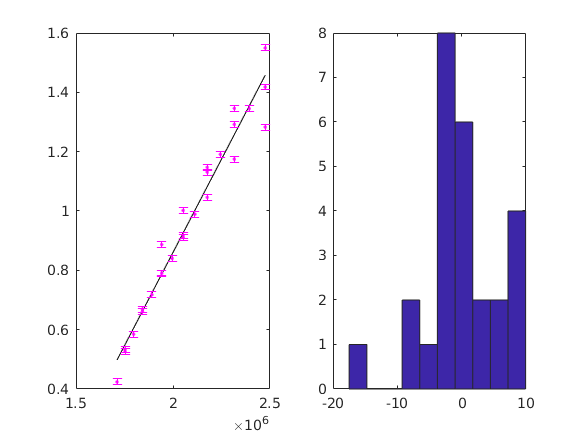


%plot(line, [ones(size(line)) line]*B1, '-r');
%hold on
figure
subplot(1,2,1)
plot(line, [ones(size(line)) line]*B2, '-k');
hold on
%plot(x1, y1, '.');
plot(x2, y2, 'm.');
errorbar(x2, y2, y2err, 'm.')
hold off

subplot(1,2,2)
Chi=(y2-[ones(size(x2)) x2]*B2)./y2err;
hist(Chi)


subplot(l,w,5)
Chi=(y-(a+b.*x))./yerr;
[x xerr y yerr Chi]
hist(Chi)
%hold on
% plot(x, Chi2)
Chi2=sum(Chi.^2)
 %%%%%%%%%%%%%%%%%%%%%%%


data=csvread('curve_3.csv',1)
x=data(:,1);
y=data(:,2);
d=size(x)
xerr=dial_error*ones(d);
yerr=voltage_error*ones(d);

[a,aerr,b,berr]=my_fit(x, y, yerr)
B3=[ a b ]';

subplot(l,w,4)
plot(x, y, 'm.');
hold on

fit=linspace(min(x),max(x),10)';
plot(fit, [ones(size(fit)) fit]*B3, '-c');
hold off

subplot(l,w,6)
Chi=(y-(a+b.*x))./yerr;
[x xerr y yerr Chi]
hist(Chi)
%hold on
% plot(x, Chi2)
Chi2=sum(Chi.^2)


print('second', '-dpng')

function [x,err]=convert(x, xerr, calibration)
    a = calibration(1,1);
    aerr = calibration(1,2);
    b = calibration(2,1);
    berr = calibration(2,2);
    
    lambda = (x-a)./b;
    err = sqrt(xerr.^2./b^2+berr^2.*x.^2/b^4+aerr^2/b^2);
    
    x = 1e9./lambda;
    err = sqrt(err.^2./lambda.^2);
    
end
function [a,aerr,b,berr]=my_fit(x, y, yerr)
    delta = sum((y.^2)./(yerr.^2))*sum(1./(yerr.^2))-(sum(y./yerr.^2))^2;
    M=[sum(1./yerr.^2) sum(x./yerr.^2);
       sum(x./yerr.^2) sum(x.^2./yerr.^2)];
    Y=[sum(y./yerr.^2); sum(x.*y./yerr.^2)];

    a = det([Y M(:,2)])/det(M);
    b = det([M(:,1) Y])/det(M);
    B = [a b]';

    aerr=sqrt(sum(x.^2./yerr.^2)/det(M));
    berr=sqrt(sum(1./yerr.^2)/det(M));
end